# Call and Provide ROS Services

ROS supports two main communication mechanisms: topics and services. 

Topics have publishers and subscribers and are used for sending and receiving messages

*Services*, on the other hand, implement a tighter coupling by allowing **request-response** communication. 

- A *service client* sends a request message to a *service server* and waits for a response. 

- The server will use the data in the request to construct a response message and sends it back to the client. 

Each service has a **type** that determines the **structure** of the request and response messages. 

Services also have a **name** (a service topic) that is unique in the ROS network.

This service communication has the following characteristics:

- A service request (or service call) is used for one-to-one communication. A single node will initiate the request and only one node will receive the request and send back a response.

- A service client and a service server are tightly coupled when a service call is executed. The server needs to exist at the time of the service call and once the request is sent, the client will block until a response is received.

Below are two different images that highlight different aspects of the service communication:

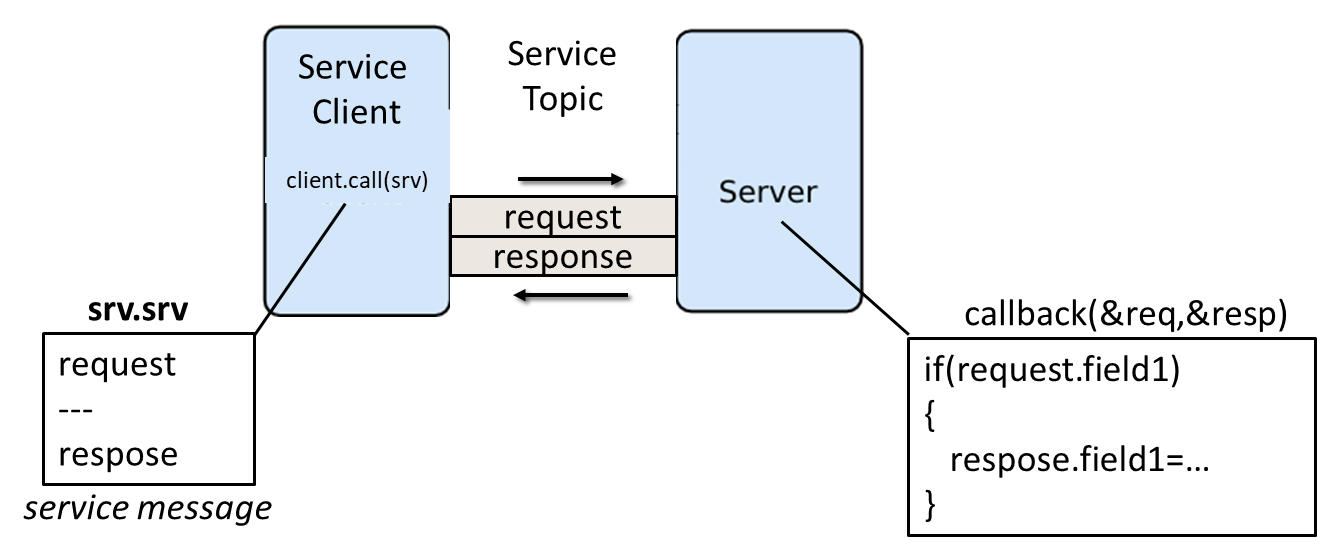            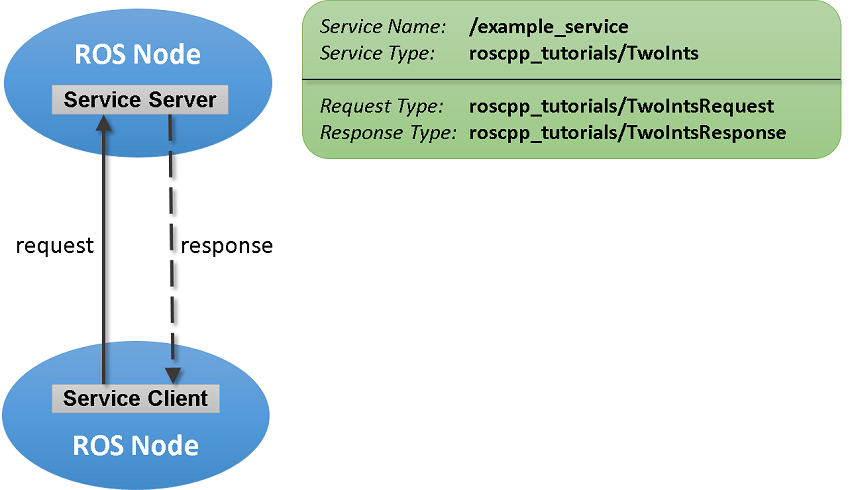

This live notebook shows you how to:

- Create a callback function that will tell the server what to do

- Create service servers via `ros.ServiceServers` (or `rossvcserver` ) to advertise a service to the ROS network. 

- Create service messages via the `rosmessage` function

- Create service clients via `ros.ServiceClient` (or rossvcclient) to issue requests to the server.

- Find information about services in the network via the `rosservice` helper method.

In its simplest form, the code could look as follows:

server = rossvcserver('/test', 'std_srvs/Empty', @exampleHelperROSEmptyCallback, 'DataFormat', 'struct')
client = rossvcclient('/test','DataFormat','struct');
call(client)

Let's flesh out more of the details and possibilities.

## 01 Toy Example

### A. Create Service Server

### rosservice list

Earlier we learned to loook at special ros helper methods like rosnodes or rostopic:

rosnode list

rostopic list

Services have a similar helper method `rosservice`:

rosservice list

rosservice info /matlab_global_node_44444/get_loggers
rosservice type /matlab_global_node_44444/get_loggers

We are now ready to explore service servers. 

Suppose you want to make a simple service server that displays the following message when the client calls:

        `-------------------------------------------------------------------`

        `Service Server is running.`

        `ROS Service client issued a call`

        `Would normally process input resp and produce a useful output again in resp`

        `-------------------------------------------------------------------`

To this end, 

- Create the service server using the ros.ServiceServer (or [`rossvcserver`](docid:ros_ref.bupf5_j_11)`)` command. You will need to specify a few things:

- Specify the host node

- Specify the service topic

- Specificy the service message type

- Specify a "**callback function**" which will specify the behavior of the server. Callbacks will take a function handle @. The function will be defined in a separate .m file. This function will require the following declaration style: 

`        function`` response = serviceCallback(src,reqMsg,defaultRespMsg,userData)`

- Specify a structure data format.

For faster performance, use services with messages in structure format.

node = ros.Node('node');
test_server = ros.ServiceServer(node, ...                              % Node
                                "/test", ...                             % Service Topic
                                "std_srvs/Empty", ...                    % Service msg type
                                {@exampleHelperROSEmptyCallback,0}, ...  % Callback with its input arguments, 0 in this case
                                "DataFormat","struct")                   % Structure

After creating the rosservice server object, you can identify this service by its service topic `/test` when you list all services in the ROS network.

rosservice list

You can get more information about your service using [`rosservice`](docid:ros_ref.bupf5_j_7)` info`. The global node is listed as node where the service server is reachable and you also see its `std_srvs/Empty` service type. 

rosservice info /test

#### Callback Function

Let's take some time to analyze the callback function. 

The callback function will be an independent m file with a declaration of the following type:

`    resp = ``callback_function_name``(~,~,resp, userData)`

This is how callbacks work:

- Call back functions get automatically called anytime a client makes a request via the `call `method (we will see this soon).

- The request message gets copied into resp. 

- The body of the callback function will take resp, use its value to do an operation, and then set the answer back into rep sending it out. 

- The client then receives the output answer and sets it equal to its output variable. 

- The output variable can then be used to do further operations.

Let's take a look at a toy callback:

exampleHelperROSEmptyCallback

### Creating a ROS Service Client

Use service clients to request information from a ROS service server. 

To create a client object, use ros.ServiceClient( or [`rossvcclient`](docid:ros_ref.bupf5_j_10)`)` call that takes:

- a service topic name and

- a struct data format

Let's create a service client for the `/test` service that we just created.

test_client = rossvcclient("/test", ...              % Service topic
                           "DataFormat","struct")    % Structure

### ROS Service Messages

ROS Service clients need to have service messages that corresponds to the service topic type. 

When we called test_server, we set its type as "std_srvs/Empty. 

We can use rosmessage to create a service message of this type in two ways:

- Pass the type directly (i.e. "std_srvs/Empty")

- Pass a service object to the message (either test_server or test_client)

test_req = rosmessage(test_server)          % Create your test request message
% test_req = rosmessage(test_client)        % Other possibilities
% test_req = rosmessage("std_srvs/Empty")

### Having the Client Call the Server

In the next section, we will make our first call from the client to the server. There are two general steps we need to follow:

- Confirm the service server exists (do not assume it exists, things can fail to start/crash or plain forget to launch it!)

- Try to make a connection to the server

- Only when the connection exists, make the call

01 Confirm the Service Server exists via `waitForServer.`

`waitForServer `takes 2 input arguments: 

- Service Client Object

- A tuple 'Name', 'Value' to establish the timeout time.

If the service server exists, waitforServer exits without error. If it does not exist it will send out an exception (or error) saying that the /test service was not available.

waitForServer(test_client,"Timeout",3) % todo: this is best done inside a try-catch block to catch exceptions. 

Once we confirm the existence of the server, we use the [`call`](docid:ros_ref.buqbgqj) function to call the service server which will return a response. 

- In this case, the test service server you created before will return an empty response. 

- At this time, you might want to put a break point inside `exampleHelperROSEmptyCallback` to see how it gets called when we issue the call method. That callback will display the string *"A service client is calling", *which will show in your command window. 

- As with waitForServer, it is possible to set a `Timeout` parameter to ensure that we receive a timely response. Otherwise a fix needs to be in place.

[test_resp,status,status_text]  = call(test_client, ...   % Client object has access to the service topic
                                     test_req, ...        % Service message, currently empty
                                     "Timeout",3)         % Timeout

Call issues 3 outputs:

- `test_resp:` contains the output of the server and would be used to then further do something in your code.

- `status`:  true or false indicates success or faillure

- `status_text: string indicating state of service server... i.e. what kind of failure might have ocurred`

### Handling Broken Connections

Let's consider a case where the Service Server does not exist or has failed for some reason. 

Delete your service server object:

clear test_server

Let's issue the waitForServer call once again:

waitForServer(test_client,"Timeout",3)

#### Try-Catch Block

We do not want our code to fail. Otherwise it crashes and prevents further execution. 

A way to handle errors in programming is through what is called a 'try-catch' block. 

You put the code you want to test inside the try block, if it fails, you do whatever is in the catch. 

Inside the try block we call `waitForServer` to check if we can connect to the server. 

If that fails, display a warning message and perhaps re-start the test_server, or choose another operation...

try
    waitForServer(test_client,"Timeout",3)
    disp('Successfully connected to the service server...')
catch
    disp('No service server running. Try running again...')
    test_server = ros.ServiceServer(node_3,"/test","std_srvs/Empty",@exampleHelperROSEmptyCallback,"DataFormat","struct") 
end

Similarly, another round of checks can happen when we call the server from the client. 

We can again use a try-catch block or alternatively use the status output of call and use that to inform a decision. 

See this example:

numCallFailures = 0;
[test_resp,status,statustext] = call(test_client, test_req, "Timeout",3);

% Use conditional statements to proceed

% Failure
if ~status % I.e. failure (when call fails, status = 0. ~0 is the same as true. So, we enter this section upon failure.

    numCallFailures = numCallFailures + 1;
    fprintf("Call failure number %d. Error cause: %s\n", numCallFailures, statustext)

% Success
else
    % Display the output of your server via test_resp
    disp(test_resp) % We use display here since we know the server only produces a string output. 
end

## 02 Create a Service for Adding Two Numbers

Up to now, the service server has not done any meaningful work, but you can use services for computations and data manipulation. Create a service that adds two integers.

There is an existing service type, `roscpp_tutorials/TwoInts`, that we can use for this task. You can inspect the structure of the request and response messages by calling `rosmsg show`. The request contains two integers, `A` and `B`, and the response contains their addition in `Sum`.

rosmsg show roscpp_tutorials/TwoIntsRequest

rosmsg show roscpp_tutorials/TwoIntsResponse

Create the service server with this message type and a callback function that calculates the addition. For your convenience, the `exampleHelperROSSumCallback` function already implements this calculation. Specify the function as a callback.

sumserver = rossvcserver("/sum","roscpp_tutorials/TwoInts",@exampleHelperROSSumCallback,"DataFormat","struct")

To call the service server, you have to create a service client. Note that this client can be created anywhere in the ROS network. For the purposes of this example, we will create a client for the `/sum` service in MATLAB.

sumclient = rossvcclient("/sum","DataFormat","struct")

Create the request message. You can define the two integers, `A` and `B`, which are added together when you use the [`call`](docid:ros_ref.buqbgqj) command.

sumreq = rosmessage(sumclient);
sumreq.A = int64(2);
sumreq.B = int64(1)

The expectation is that the sum of these two numbers will be 3. To call the service, use the following command. The service response message will contain a `Sum` property, which stores the addition of `A` and `B`. Ensure that the service server is available before making a call, and react appropriately if it is not.

if isServerAvailable(sumclient)
    sumresp = call(sumclient,sumreq,"Timeout",3)
else
    error("Service server not available on network")
end

## Shut Down ROS Network

Remove the sample nodes and service servers from the ROS network.

exampleHelperROSShutDownSampleNetwork

Shut down the ROS master and delete the global node.

rosshutdown

*Copyright 2014-2021 The MathWorks, Inc.*